close all;
clear all;
clc;
img1=imread('brain2.jpg');
img=im2gray(img1);
bw=imbinarize(img,0.7);
label=bwlabel(bw);
stats=regionprops(label,'Solidity','Area')

stats = 21×1 struct array with fields:
    Area
    Solidity


density=[stats.Solidity];
area=[stats.Area];
high_dense_area=density>0.7

high_dense_area = 1×21 logical array
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   1


max_area=max(area(high_dense_area))

max_area = 13

tumor_label=find(area==max_area)

tumor_label = 21

tumor=ismember(label,tumor_label)

tumor = 268×220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

se=strel('square',5)

se = strel is a square shaped structuring element with properties:

      Neighborhood: [5×5 logical]
    Dimensionality: 2


tumor=imdilate(tumor,se)

tumor = 268×220 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

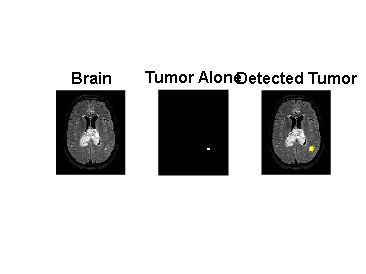

figure(2)
subplot(1,3,1);
imshow(img,[]);
title('Brain');

subplot(1,3,2);
imshow(tumor,[]);
title('Tumor Alone');
[B,L]=bwboundaries(tumor,'noholes');
subplot(1,3,3);
imshow(img,[]);
hold on
for i=1:length(B)
    plot(B{i}(:,2),B{i}(:,1), 'y' ,'linewidth',1.45);
    
    
    
end

title('Detected Tumor');
hold off;